# Plot Turbulence Empirical RSN filt (0.08-0.008)

Plot results from the empirical analysis: turbulence, information flow, information cascade and information transfer obtained in turbulence_empirical_RSN.mlx. 

TBI dataset from OpenNeuro: [https://openneuro.org/datasets/ds000220/versions/1.0.0/file-display/dataset_description.json](https://openneuro.org/datasets/ds000220/versions/1.0.0/file-display/dataset_description.json)

## Load results

clear all
ds1_path='/Volumes/LASA/TBI_project/TBI_openneuro/timeseries/outputs/Turbulence_28_03_2022/';
ds2_path='/Volumes/LASA/TBI_project/TBI_Helsinki/timeseries/pre_post_schaefer1000/outputs/Turbulence_16_03_2022/';
output_path='/Volumes/LASA/TBI_project/TBI_openneuro/timeseries/outputs/Turbulence_ds1ds2_age_30_03_2022/';
addpath '/Users/noeliamartinezmolina/Documents/GitHub/TBI_turbulence_openneuro_current_code/helper functions'
lambda={'0.27','0.24','0.21','0.18','0.15','0.12','0.09','0.06','0.03','0.01'};
cond = {'Controls','Patients'};
% dataset 1 Open Neuro
cd(ds1_path)
ds1_results = load(sprintf('turbubyRSN_all_measurements_cond1.mat'));
idx_con=[1:1:12]; idx_pat=[13:1:24];
ds1_TurbubyRSN_con= ds1_results.TurbulenceRSN_sub(:,idx_con,:);
ds1_TurbubyRSN_pat= ds1_results.TurbulenceRSN_sub(:,idx_pat,:);

% dataset 2 Helsinki
cd(ds2_path)
ds2_results = load(sprintf('turbubyRSN_all_measurements_cond1.mat'));
idx_ds2=sort([3 16 4 5 17 19 6 7 20 8 9 21 11 12 22 13 14 23 15]);
ds2_TurbubyRSN_pat= ds2_results.TurbulenceRSN_sub(:,idx_ds2,:);

% Merge ds1 & ds2
ds1ds2_TurbubyRSN_pat=horzcat(ds1_TurbubyRSN_pat, ds2_TurbubyRSN_pat);
cd(output_path)

## Plot turbulence by RSN

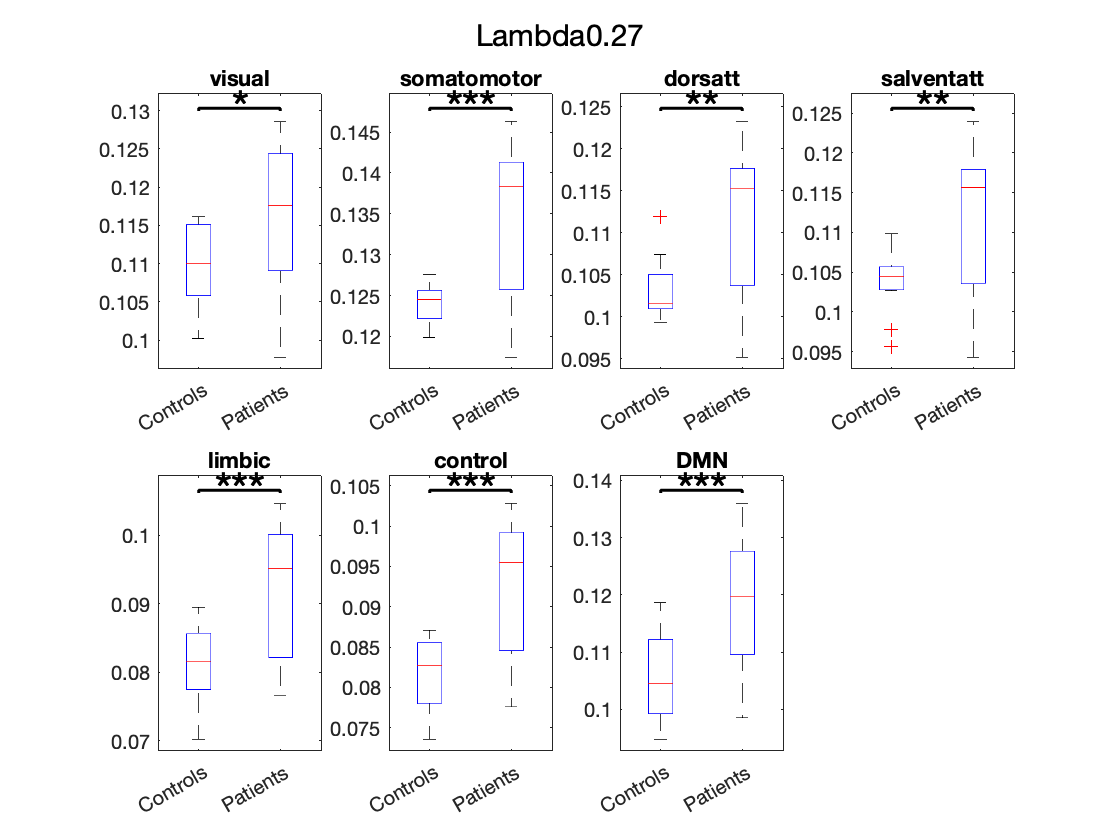

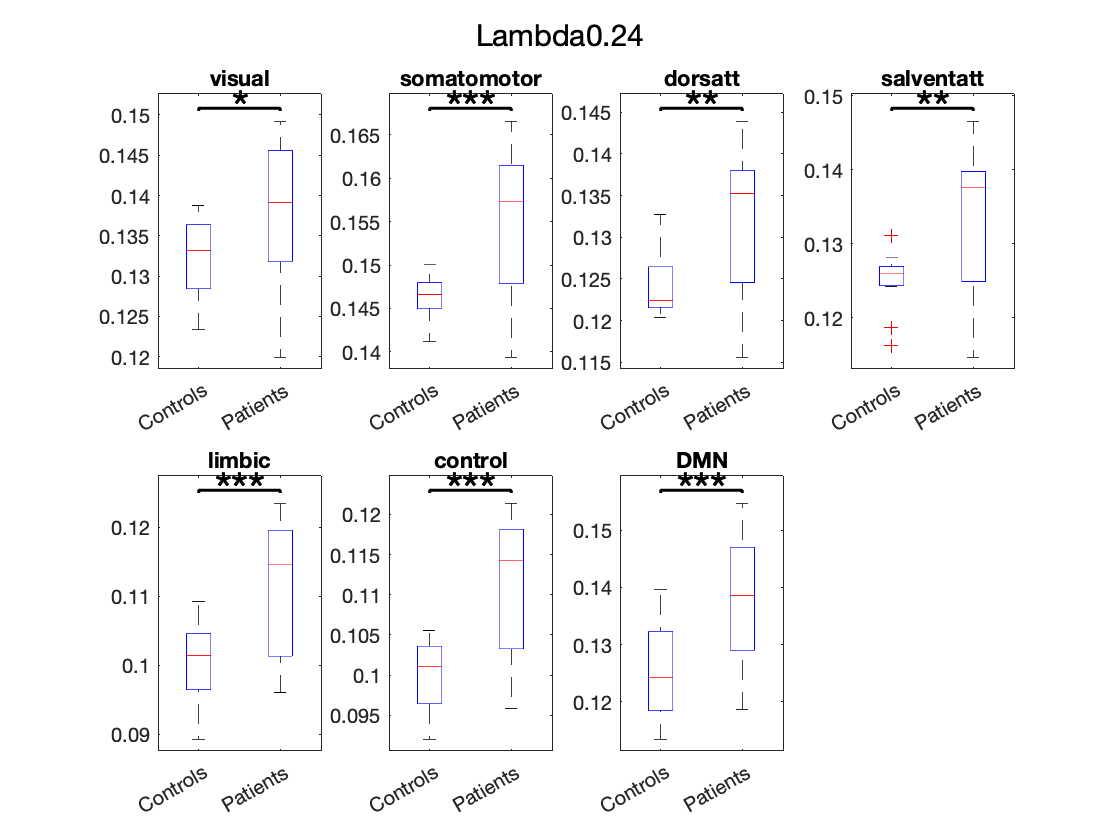

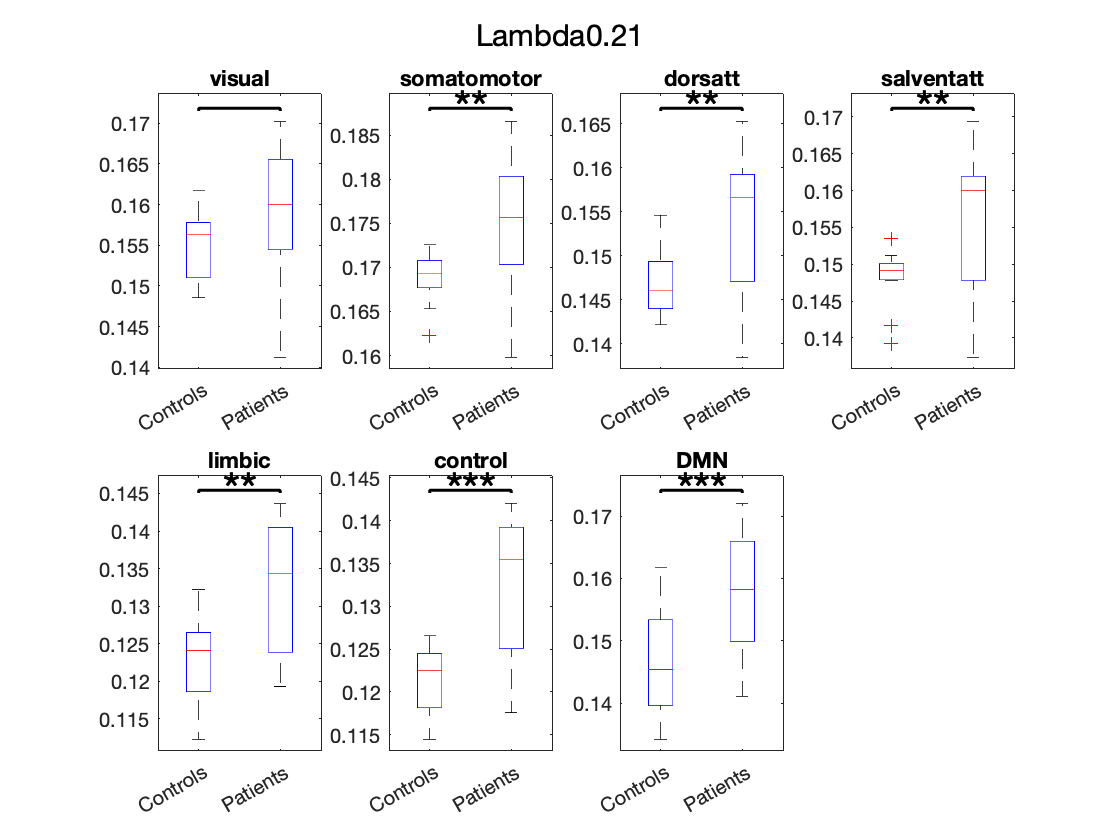

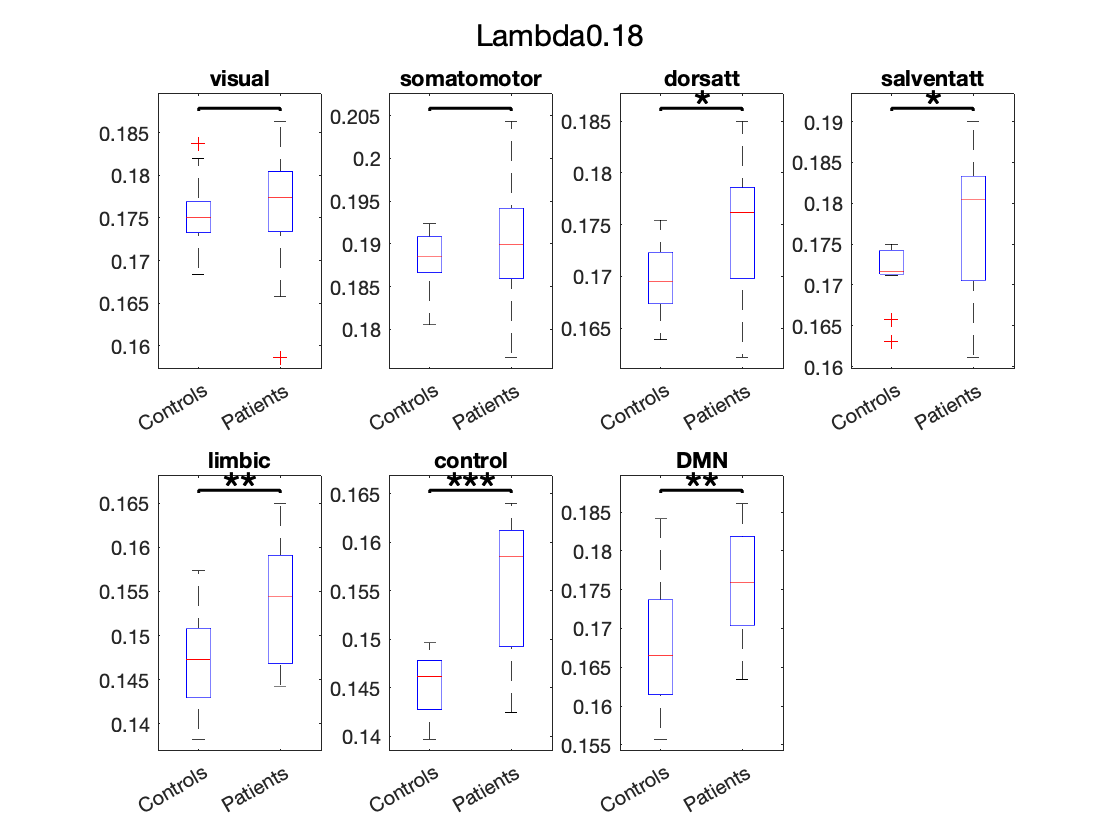

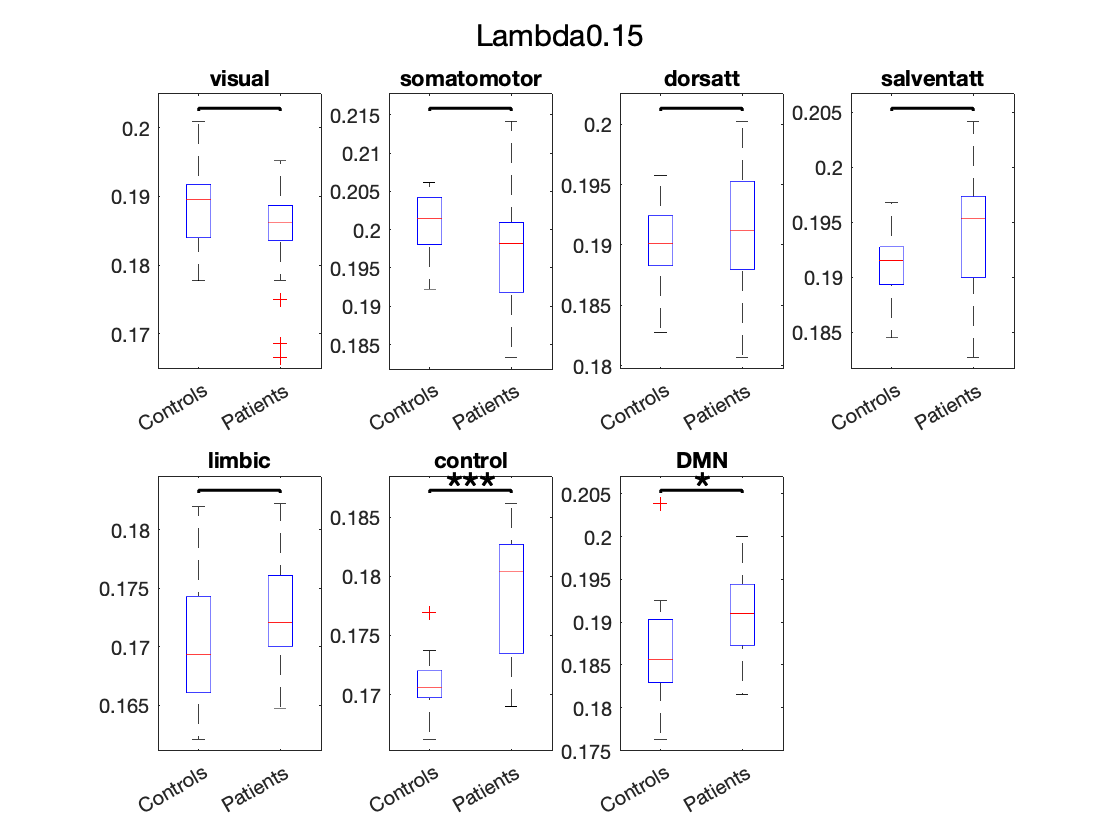

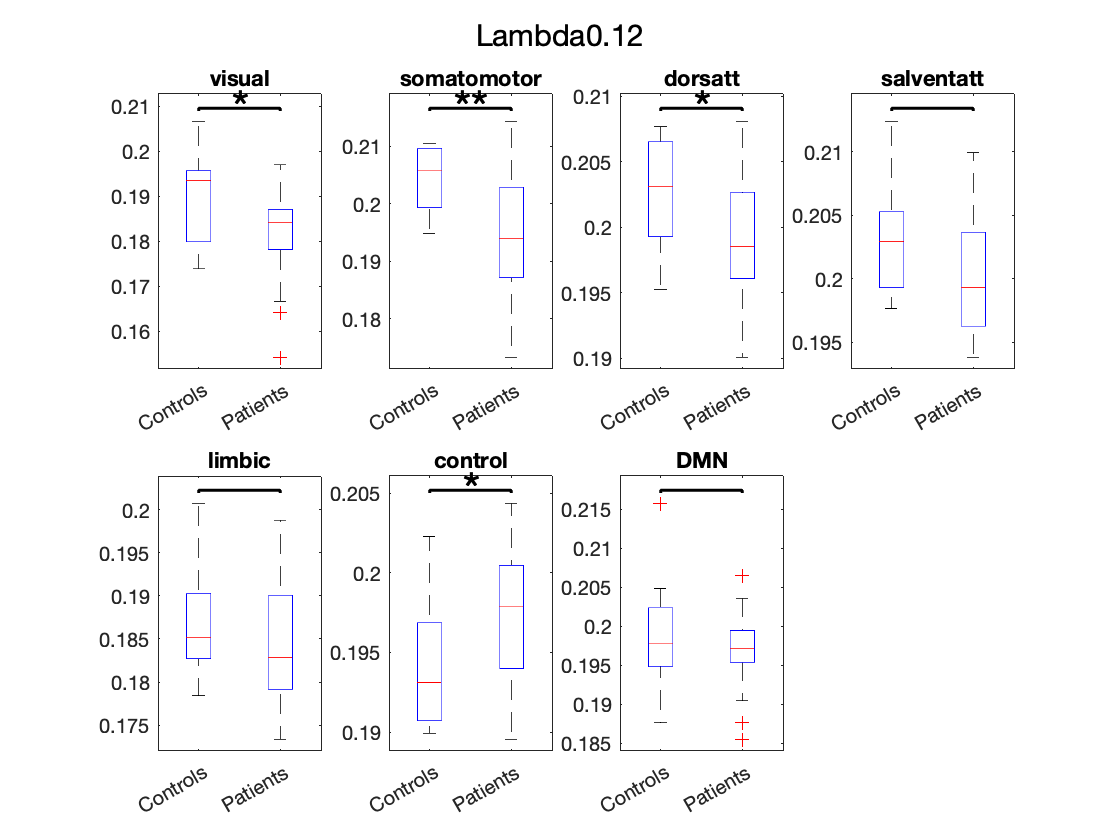

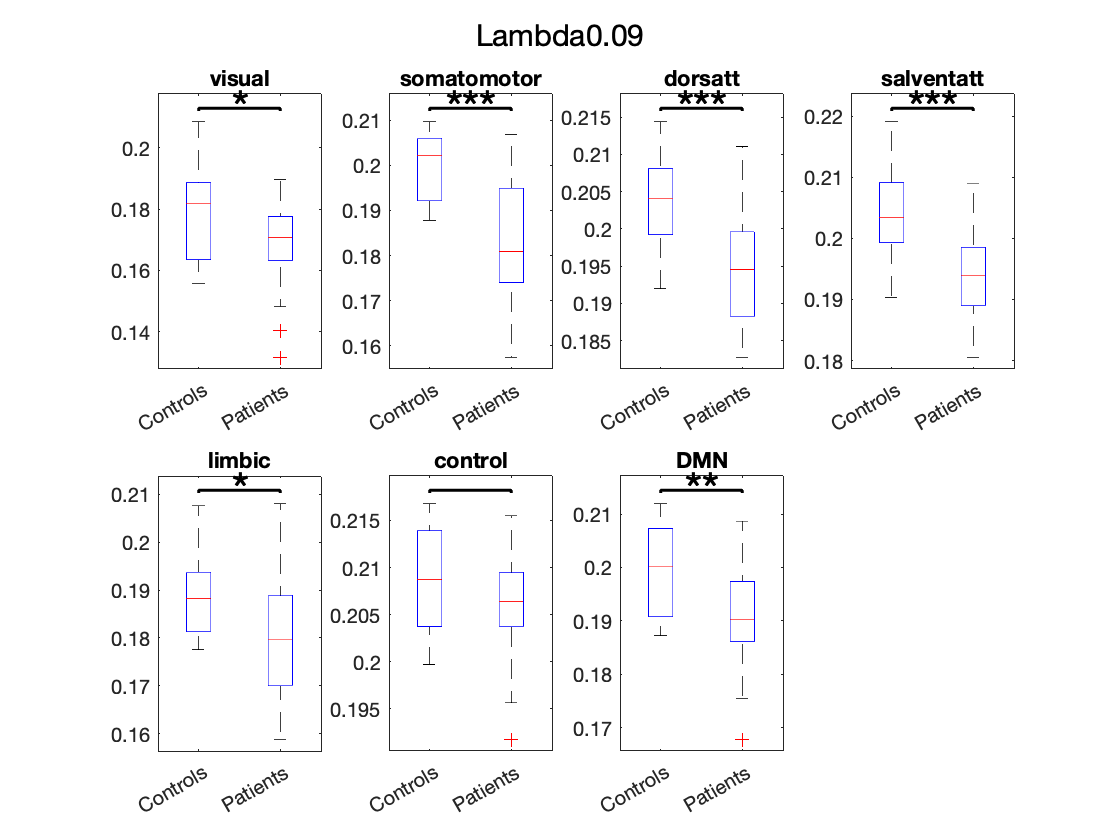

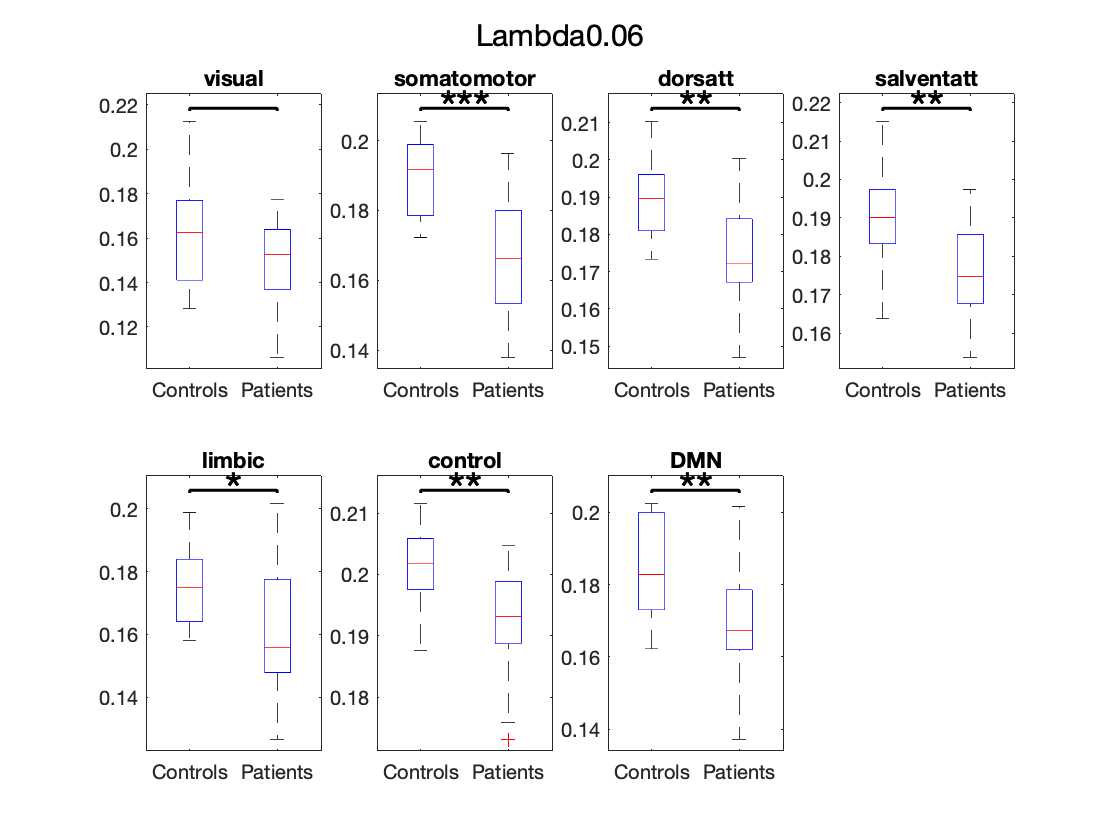

Rsns = {'visual', 'somatomotor','dorsatt','salventatt','limbic','control','DMN'};
for lamb=1:length(lambda)
    figure
    sgtitle (['Lambda' char(lambda(lamb))])
    for jj=1:7 %Loop for networks
        subplot(2,4,jj)
        C = {ds1_TurbubyRSN_con(lamb,:,jj) , ds1ds2_TurbubyRSN_pat(lamb,:,jj)};
        maxNumEl = max(cellfun(@numel,C));
        Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
        Cmat = cell2mat(Cpad);
        boxplot(Cmat,'Labels',cond)
        title(Rsns{jj})
        
        [~,pval] = ttest2(ds1_TurbubyRSN_con(lamb,:,jj),ds1ds2_TurbubyRSN_pat(lamb,:,jj)); % paired t Test
        p(1,jj)=pval; clear pval
        H=sigstar({[1,2]},p(1,jj));
    end
    print(['TurbulencebyRSN Open Neuro TBI (N=43) filt lambda' num2str(lamb)],'-dpng')
end